% SSBSC
clc;
clear;
fs=4000;
t=0:1/fs:1;
t=linspace(0,1,1000);

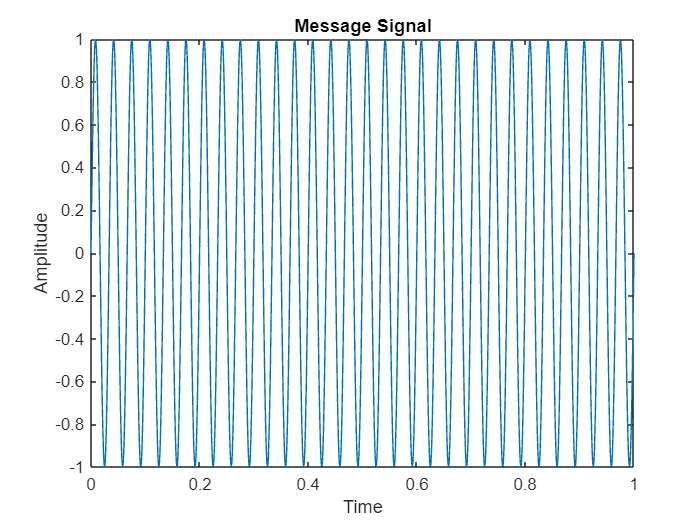

% Message signal
fm=30;
Am=1;
mt=Am*sin(2*pi*fm*t);
plot(t,mt);
xlabel("Time");
ylabel("Amplitude");
title("Message Signal");

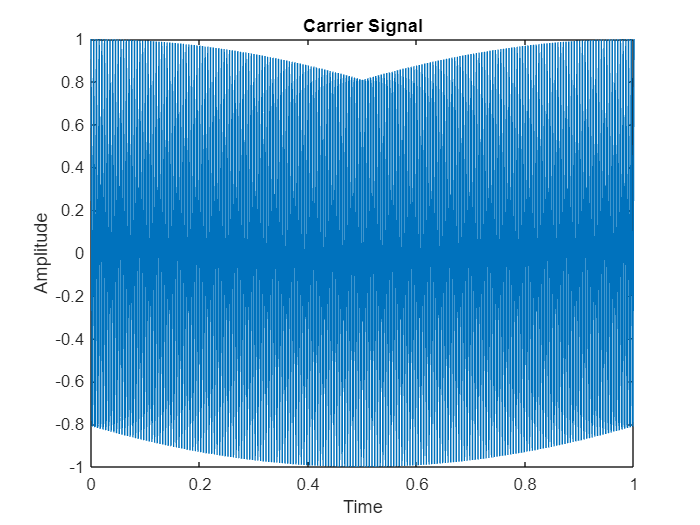

% Carrier Signal
fc=200;
Ac=1;
ct=Ac*cos(2*pi*fc*t);
plot(t,ct);
xlabel("Time");
ylabel("Amplitude");
title("Carrier Signal");

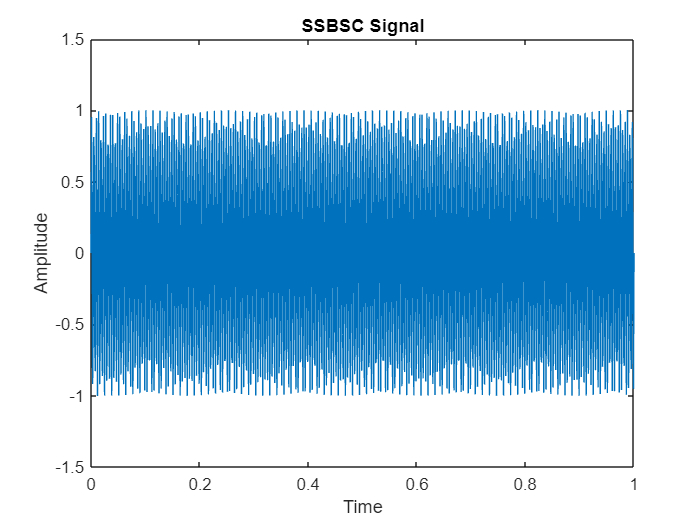

% SSBSC signal
mh=imag(hilbert(mt));
st=mt.*cos(2*pi*fc*t)-mh.*sin(2*pi*fc*t);
plot(t,st);
xlabel("Time");
ylabel("Amplitude");
title("SSBSC Signal");